# Filtering in the Frequency Domain

Filtering in the Frequency Domain is an image processing method where we enhance or suppress image details by working with frequency components instead of the spatial domain (pixel values)!

## 2-D FFT of an image(spatial domain ↔️ frequency domain)

`What this section proves`

`fft2 → fftshift → ifftshift → ifft2 without changing anything in between,`

`we're basically showing: ``FFT and inverse FFT can reconstruct the original image`` (up to tiny numeric errors).`

#### `Import and View the Image`

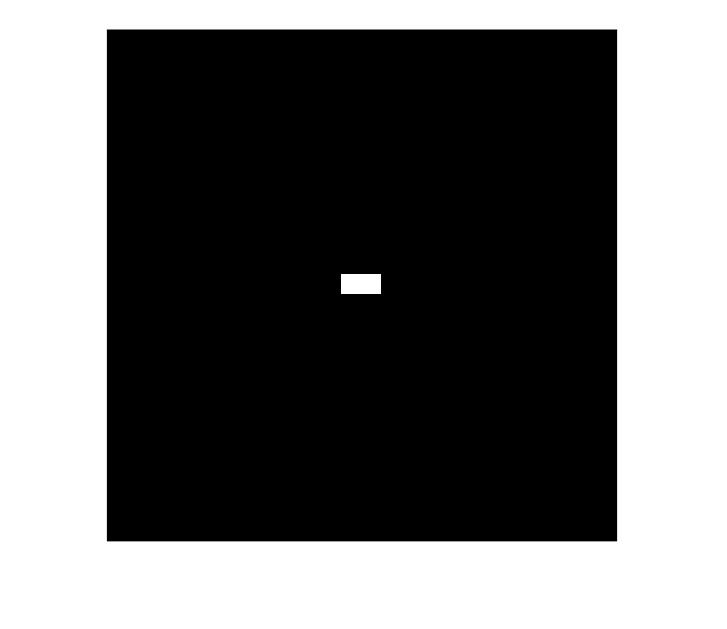

% Read image
img = imread("image.tif");
% Convert to double in [0,1]
I = im2double(img);
%Display
imshow(I,[])

#### time/space domain to frequency domain

% Forward FFT (go to frequency domain)
F = fft2(I);

% Magnitude (unshifted)
S = abs(F);

*Unshifted FFT has low frequencies at the corners, not the center, so the image looks weird/hard to interpret.*

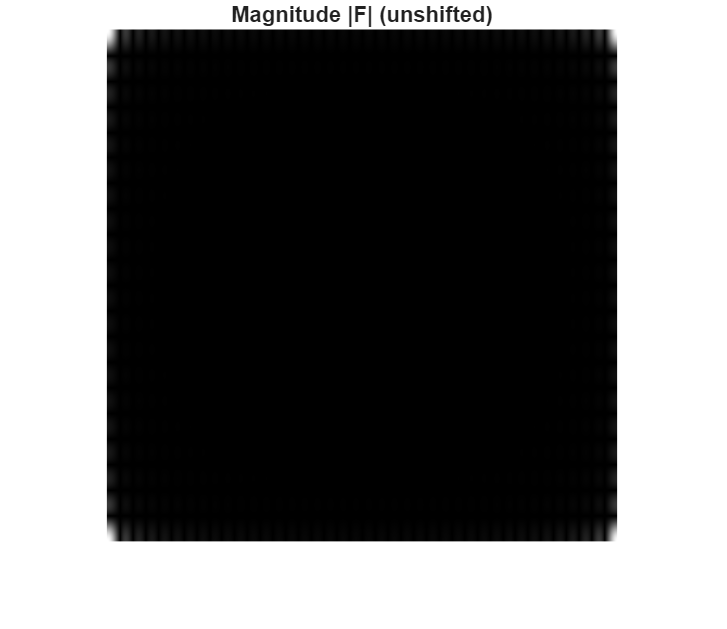

% Display 
imshow(S,[])
title("Magnitude |F| (unshifted)");

#### Shifted FFT for nicer visualization

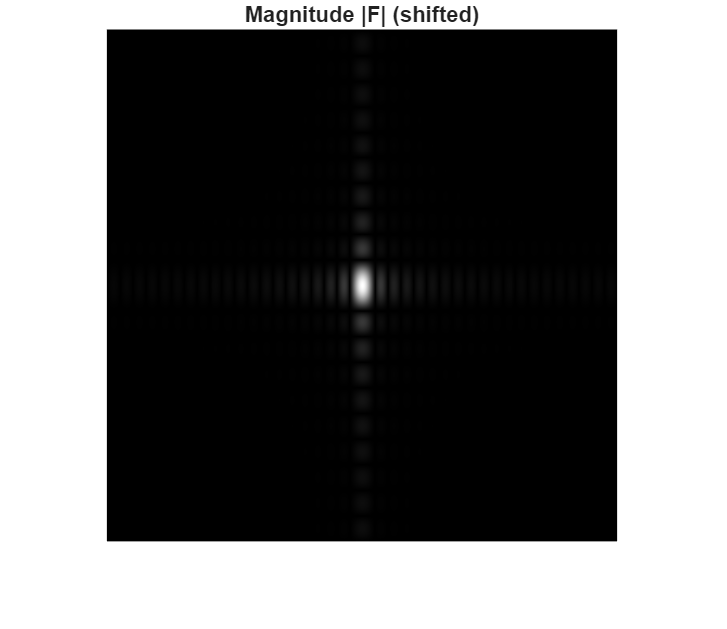

% Shifted FFT for nicer visualization
Fc = fftshift(F);
%Display 
imshow(abs(Fc),[])
title("Magnitude |F| (shifted)"); 

#### Log spectrum (better visualization)

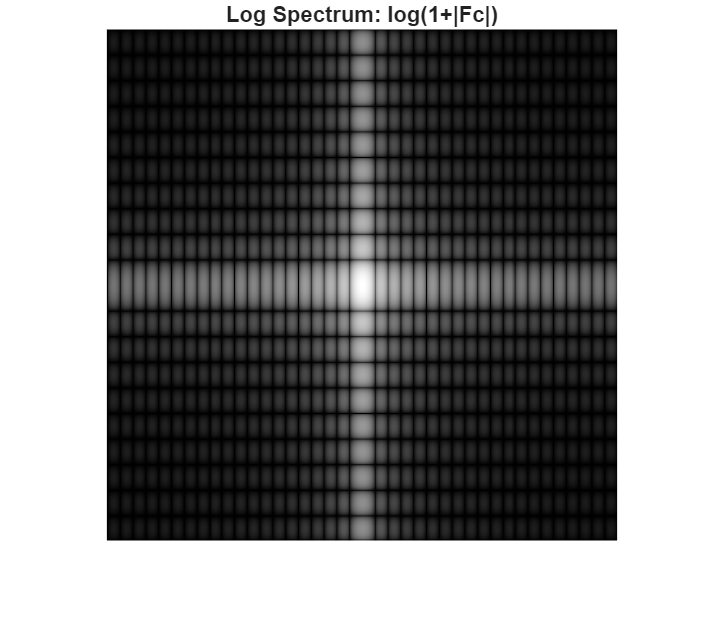

% Log spectrum (recommended)
S2 = log(1 + abs(Fc));
%Display
imshow(S2,[])
title("Log Spectrum: log(1+|Fc|)");

#### Inverse shift + inverse FFT (reconstruct image)

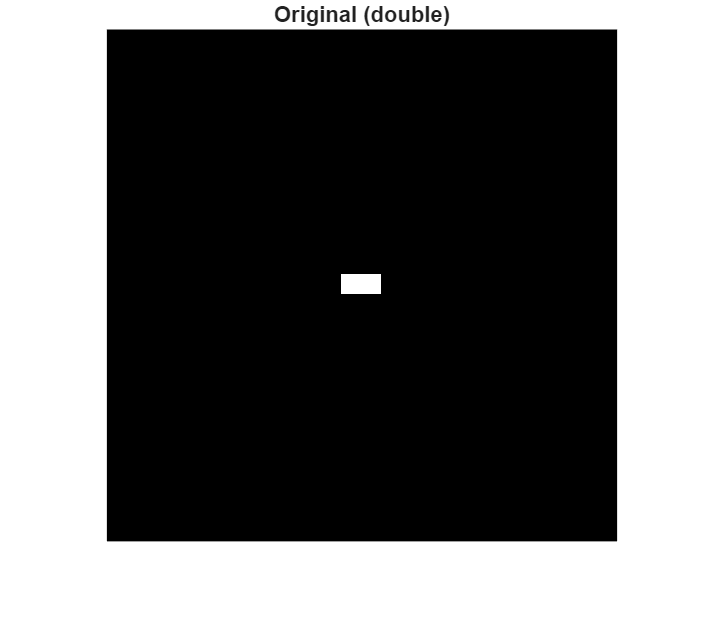

% Inverse FFT (reconstruction)
F = ifftshift(Fc);
g = ifft2(F);
g = real(g);  % remove tiny numerical imaginary parts
% Display       
imshow(g)
title("Original (double)");          

## Frequency-domain Gaussian low-pass (no padding)

#### Import and View the Image

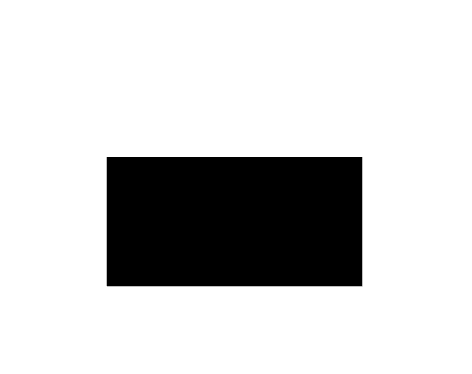

%% Read + prepare image
img1 = imread("square_original.tif");
I = im2double(img1);

%Display
imshow(I,[])

#### FFT filtering, no padding

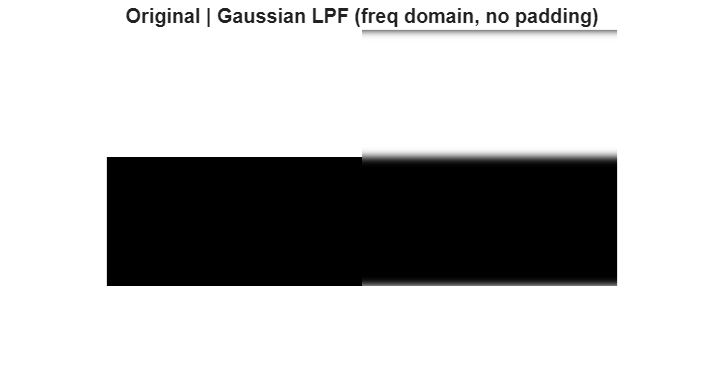

[M, N] = size(I);
%% Parameters
sigma = 10;  % Gaussian LPF parameter (your lpfilter uses this as "sig")

%% 1) Frequency-domain filtering (no padding)
F  = fft2(I);
H  = lpfilter("gaussian", M, N, sigma);   % assumes lpfilter returns centered/ready-to-multiply filter
G  = H .* F;
g  = real(ifft2(G));
imshowpair(I, g, "montage")
title("Original | Gaussian LPF (freq domain, no padding)");

## Frequency-domain Gaussian low-pass with padding

#### FFT filtering, with padding

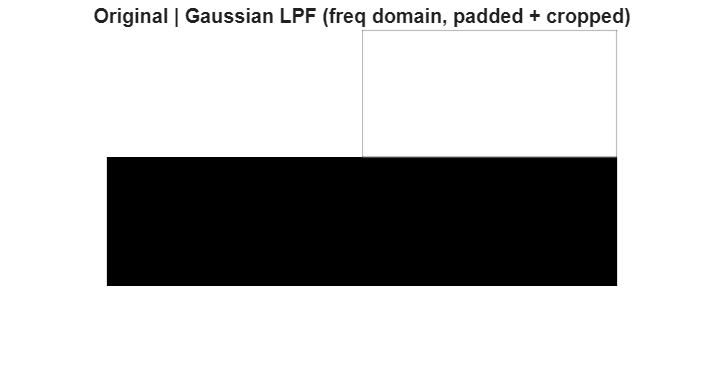

%% 2) Frequency-domain filtering (with padding) + crop back
PQ = paddedsize(size(I));         % e.g., [2M 2N] depending on your function
Fp = fft2(I, PQ(1), PQ(2));
Hp = lpfilter("gaussian", PQ(1), PQ(2), 10*sigma);  % keep your original choice (10*sigma)
Gp = Hp .* Fp;
gp  = real(ifft2(Gp));
gpc = gp(1:M, 1:N);               % crop to original size
imshowpair(I, gpc, "montage")
title("Original | Gaussian LPF (freq domain, padded + cropped)");

#### The `fspecial + imfilter` method (spatial filtering)

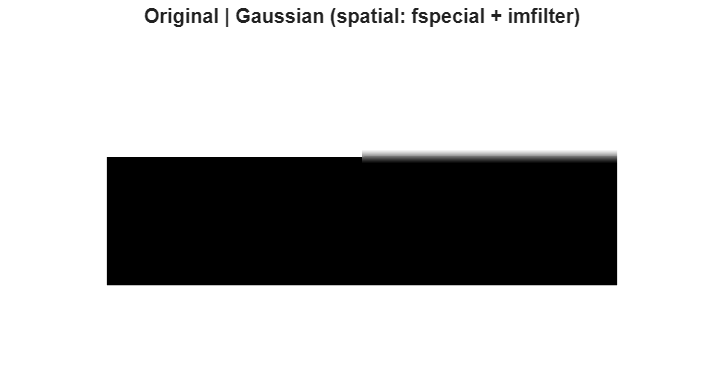

%% 3) Spatial-domain Gaussian using fspecial + imfilter
h  = fspecial("gaussian", 15, 7); % (kernelSize, sigma)
gs = imfilter(I, h, "symmetric");
imshowpair(I, gs, "montage")
title("Original | Gaussian (spatial: fspecial + imfilter)");

## **edge detection with a Sobel filter** in **two different domains**

#### Import and View the Images

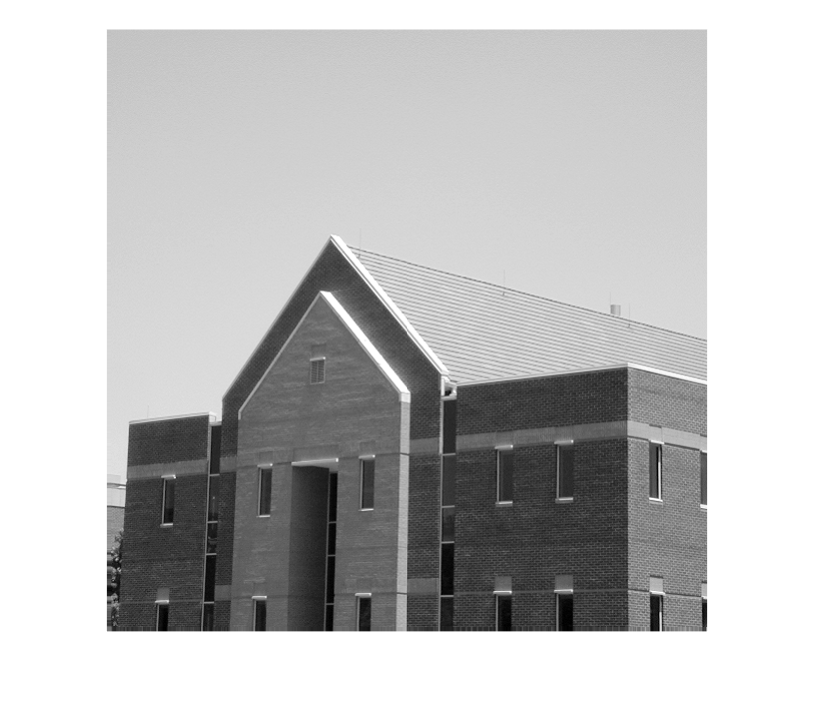

%% Read + prepare image
img2 = imread("building.tif");
f = im2double(img2);
%Display
imshow(f,[])

####  image spectrum

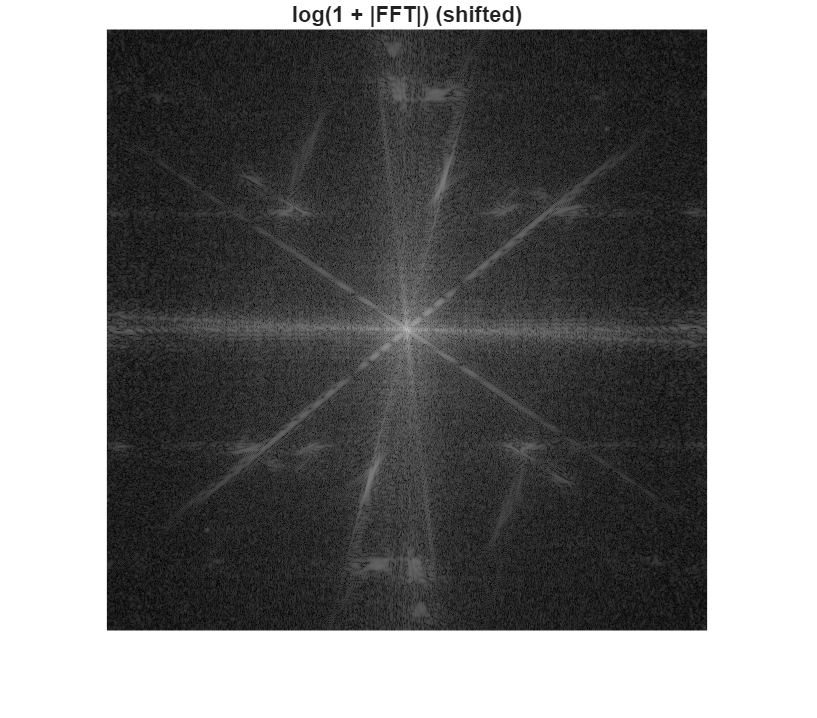

% FFT spectrum visualization (log magnitude)
F = fft2(f);
spec = fftshift(log(1 + abs(F)));
imshow(spec, [])
title("log(1 + |FFT|) (shifted)");

#### Sobel Filter Frequency Response

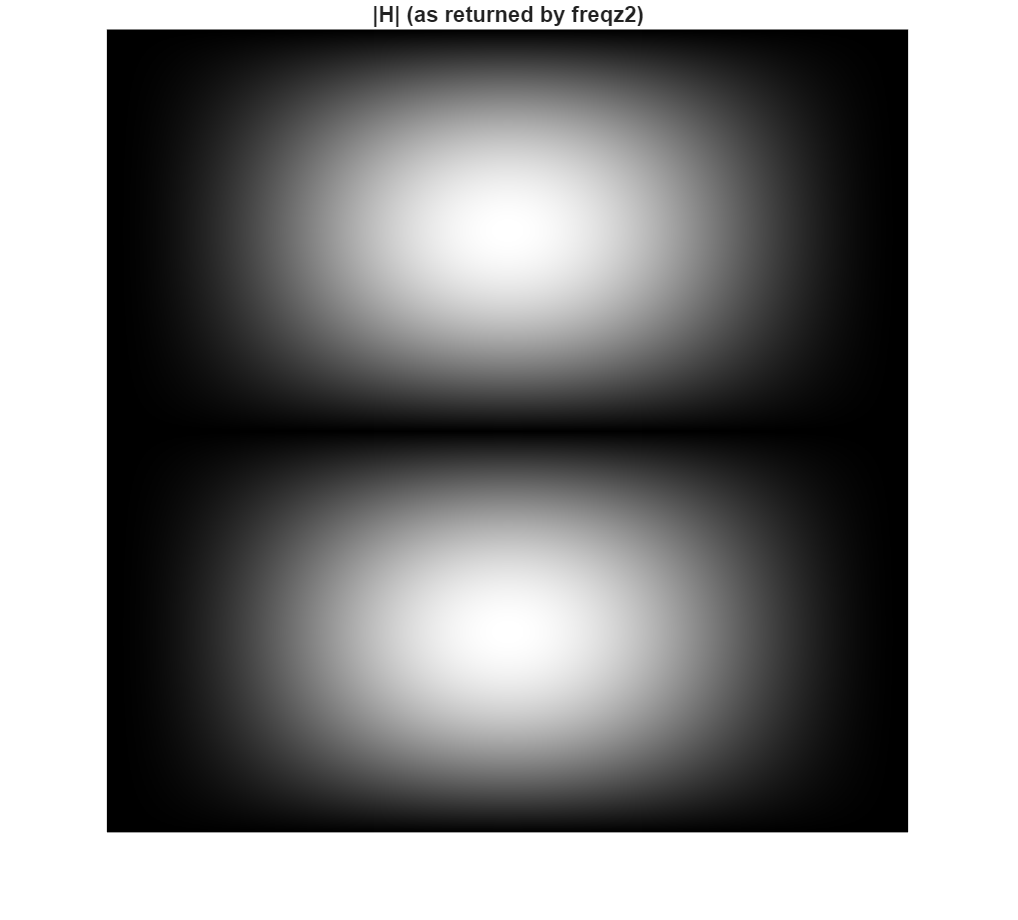

%% Create Sobel filter
h = fspecial("sobel");
% Padded size for frequency-domain filtering
PQ = paddedsize(size(f));             % assumes you have paddedsize()
% Frequency response of Sobel on padded grid
H  = freqz2(h, PQ(1), PQ(2));         % same size as padded FFT
Hc = ifftshift(H);                    % align for multiplication with fft2 result
imshow(abs(H), [])
title("|H| (as returned by freqz2)")

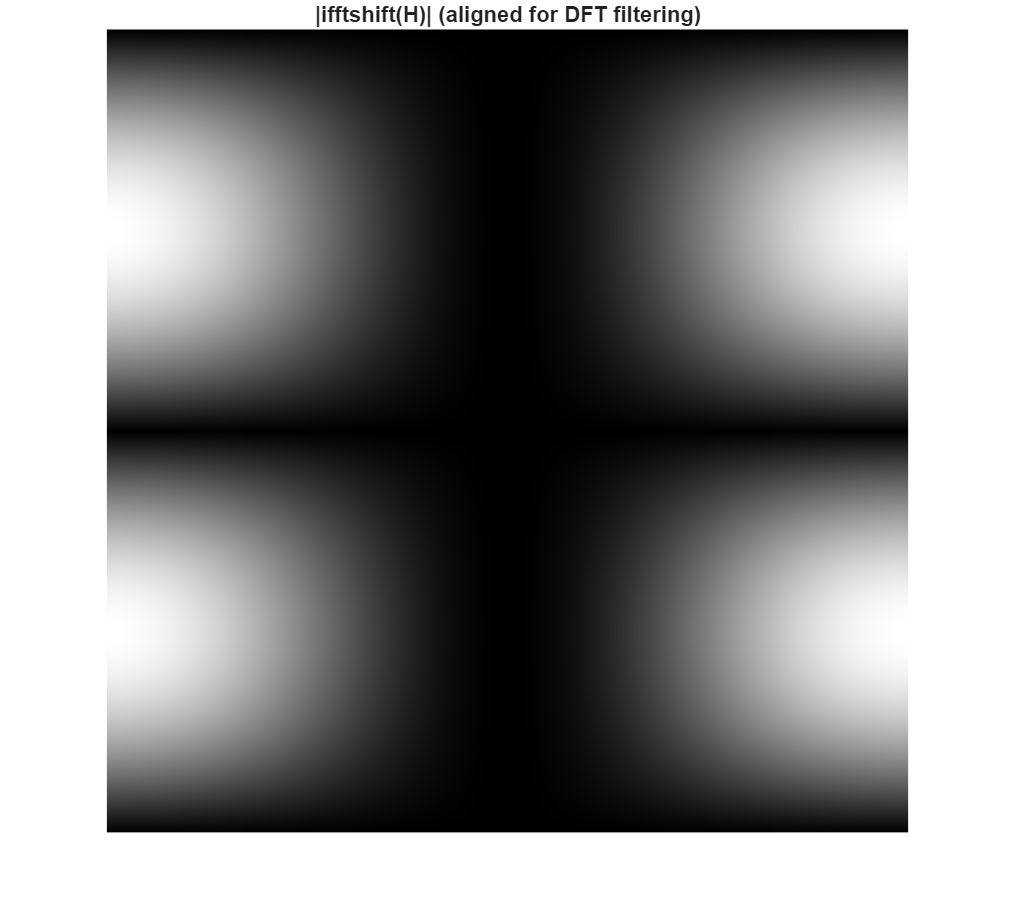

imshow(abs(Hc), [])
title("|ifftshift(H)| (aligned for DFT filtering)")

#### Comparison of Sobel Edge Detection in Spatial and Frequency Domains

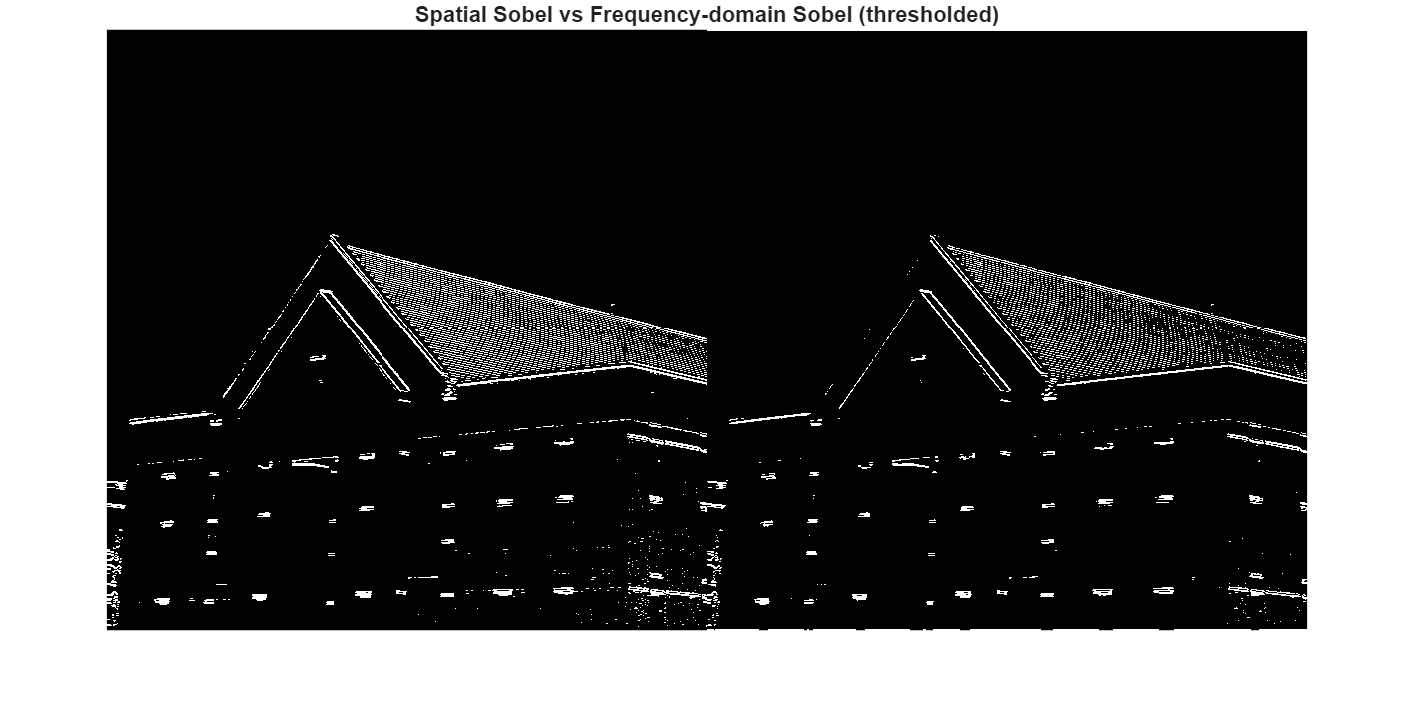

%% Apply Sobel in spatial domain vs frequency domain
gs = imfilter(f, h, "symmetric");     % spatial convolution (recommended boundary handling)
gf = dftfilt(f, Hc);                  % assumes dftfilt pads internally (Gonzalez style)
%% Compare thresholded edge maps
thrS = 0.2 * max(abs(gs(:)));
thrF = 0.2 * max(abs(gf(:)));
edgeS = abs(gs) > thrS;
edgeF = abs(gf) > thrF;
imshowpair(edgeS, edgeF, "montage")
title("Spatial Sobel vs Frequency-domain Sobel (thresholded)");

## Gaussian Low-Pass Filtering in the Frequency Domain

#### Import and View the Image

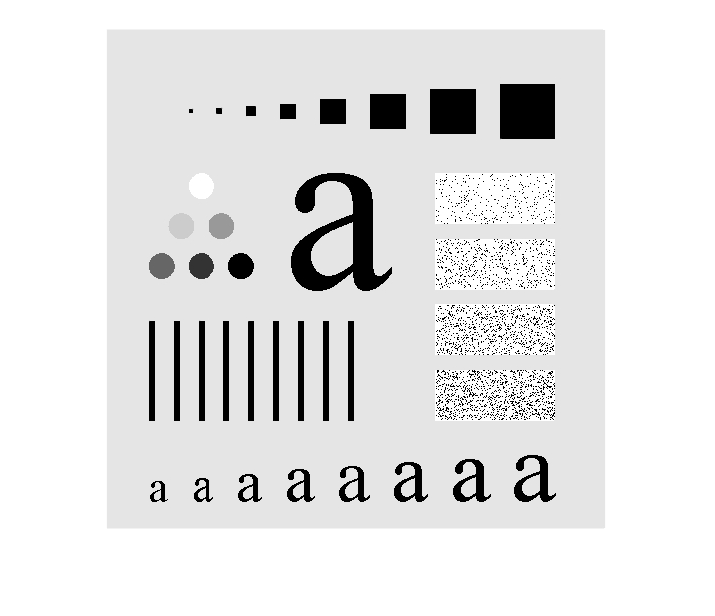

%% Read + prepare image
img3 = imread("Original.tif");
f = im2double(img3);
%Display
imshow(f,[])

#### Padded FFT-Based Gaussian High-Pass Filtering

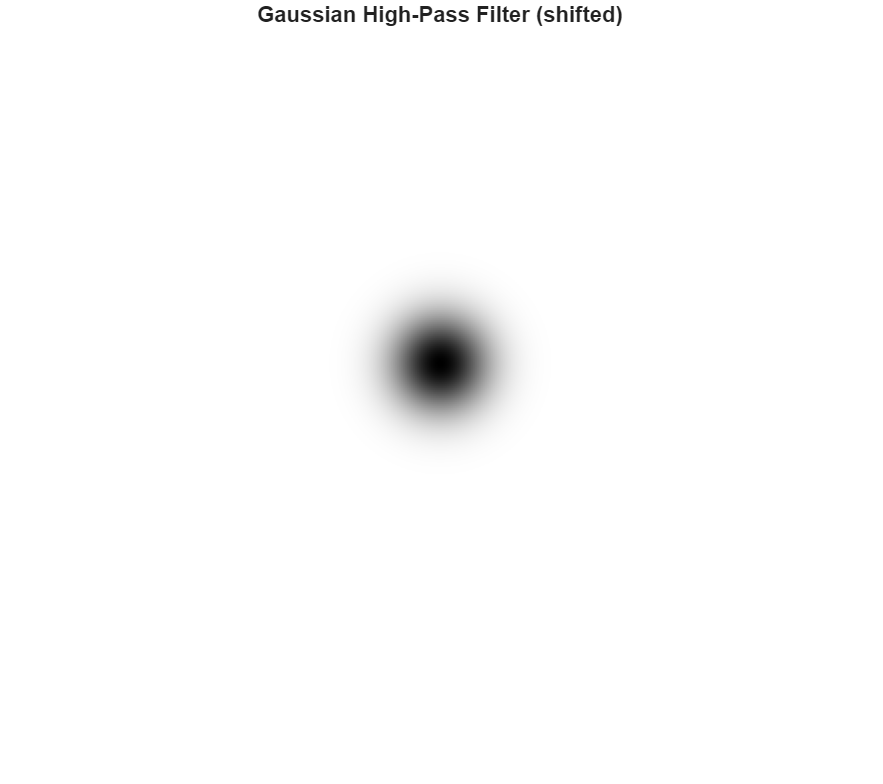

%% Padding size
PQ = paddedsize(size(f));          % e.g., [2M 2N] depending on your function

%% Frequency grid + Gaussian High-Pass filter
[u, v] = dftuv(PQ(1), PQ(2));              % your dftuv should return centered frequency coordinates
D0 = 0.05 * PQ(1);                     % cutoff radius (your choice)
D2 = u.^2 + v.^2;                  % squared distance from origin
Hlp = exp(-D2 / (2 * D0^2));       % Gaussian low-pass
H   = 1 - Hlp; % Gaussian high-pass (GHPF)

imshow(fftshift(H), []) 
title("Gaussian High-Pass Filter (shifted)");

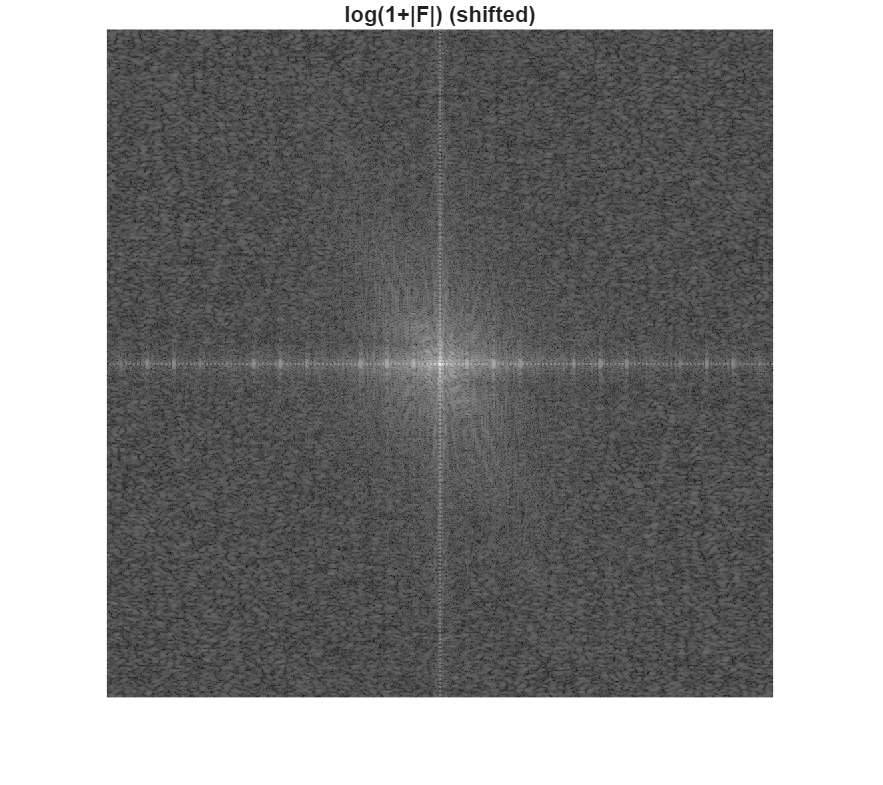

%% Apply filter in frequency domain
Fp = fft2(f, PQ(1), PQ(2));  % padded FFT

imshow(fftshift(log(1 + abs(Fp))), [])
title("log(1+|F|) (shifted)");

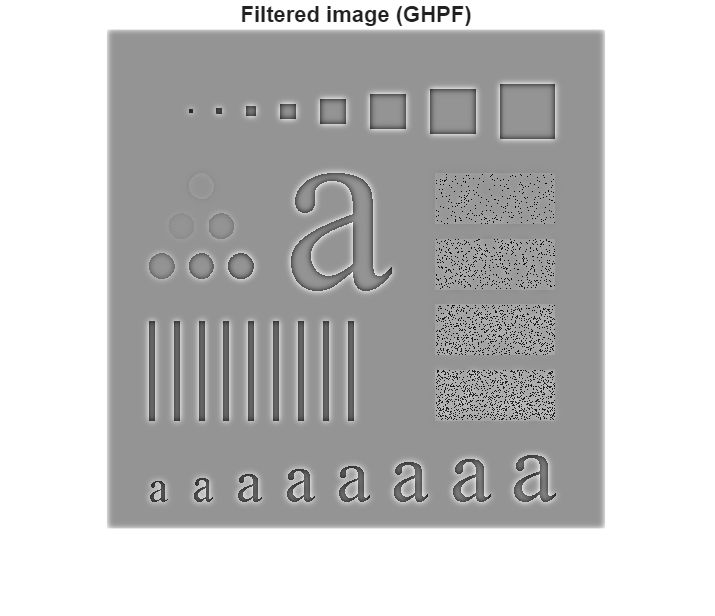

Gp = H .* Fp;                      % filtering
gp = real(ifft2(Gp));              % back to spatial
g  = gp(1:size(f,1), 1:size(f,2)); % crop to original size
imshow(g,[])
title("Filtered image (GHPF)");

## Gaussian High-Pass Filtering in the Frequency Domain

#### Import and View the Image

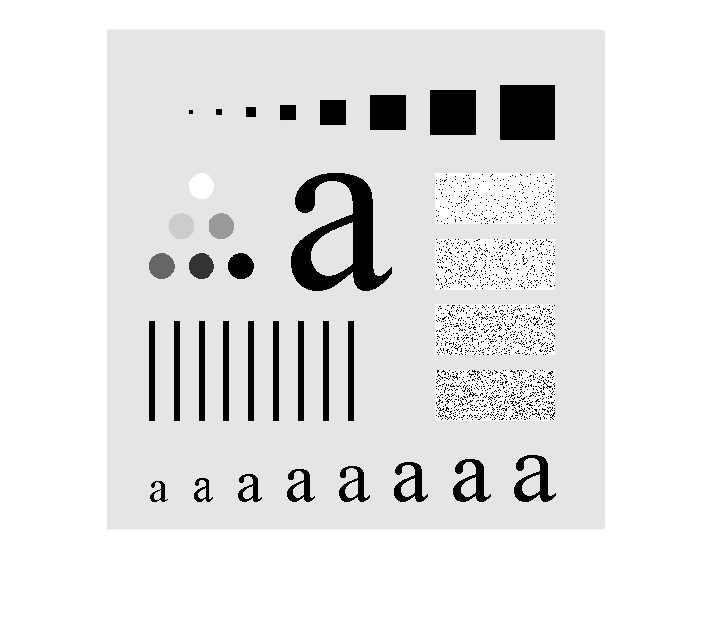

img3 = imread("Original.tif");
f = im2double(img3);
%Display
imshow(f,[])

#### DFT filtering

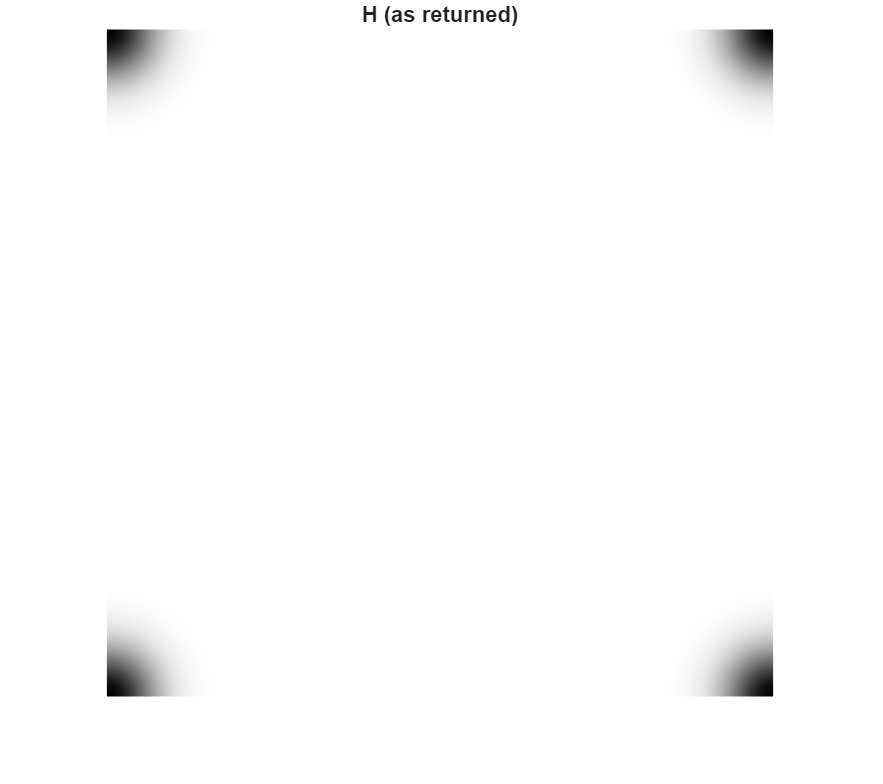

%% Padding size
PQ = paddedsize(size(f));   % e.g., [2M 2N]
%% Cutoff + Gaussian High-Pass filter
D0 = 0.05 * PQ(1);
H  = hpfilter("gaussian", PQ(1), PQ(2), D0);   % assumes hpfilter returns a frequency-domain mask

imshow(H,[])    %unshifted    
title("H (as returned)")

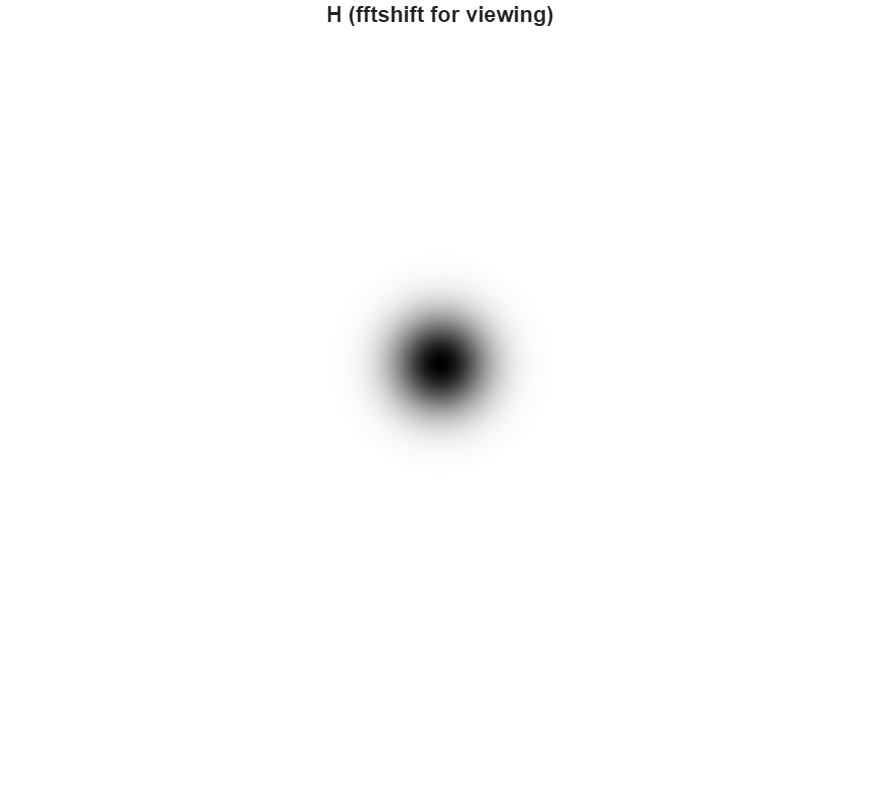

imshow(fftshift(H),[]) %shifted
title("H (fftshift for viewing)")

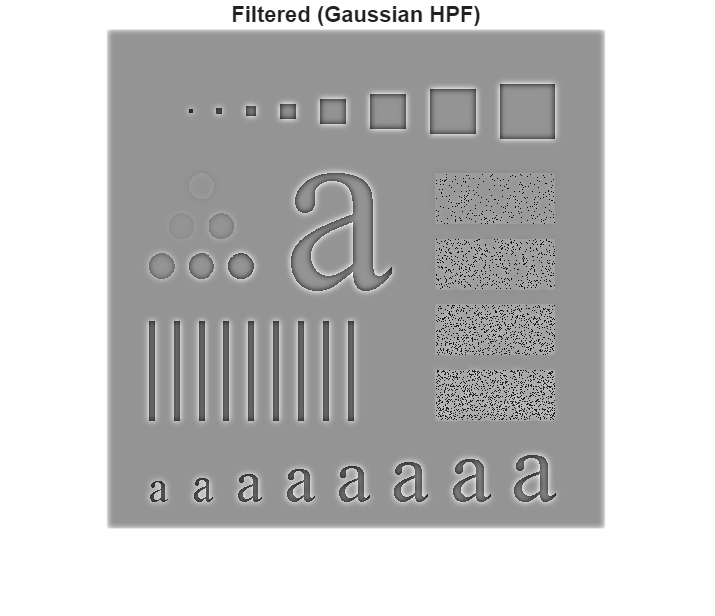

%% Apply filter (DFT filtering)
g = dftfilt(f, H);  % assumes dftfilt handles padding/cropping internally
imshow(g,[])
title("Filtered (Gaussian HPF)")